# Thermal Model Fit and Design

Copyright (C) 2023 Fondazione Istitito Italiano di Tecnologia (IIT)

All Rights Reserved.

## Read datasets

### Training set

training_measurements = "data/1.xlsx";
training_input = "data/n1.mat";
training_start_time_offset = 10000;
training_Ts = 0.01;
motor_ID = 3; % We assume that we gathered data where we logged 3 motors
[idd_training] = create_iddata(training_measurements, ...
                               training_input, training_start_time_offset, training_Ts, motor_ID);

idd_training.Name = "training";

### Validation sets

The model fitted with training data will be tested against more than one validation set

n_validation_sets = 3;
idd_validations = cell(n_validation_sets, 1);

validation_measurements = {"data/4.xlsx", "data/3.xlsx", "data/2.xlsx"};
validation_inputs = {"data/n4.mat", "data/n3.mat", "data/n2.mat"};


for i=1:n_validation_sets    
    validation_start_time_offset = 1;
    validation_Ts = 0.01;
    idd_validations{i} = create_iddata(validation_measurements{i}, ...
                                     validation_inputs{i}, validation_start_time_offset, validation_Ts, motor_ID);
    idd_validations{i}.Name = "validation";
end

### Plot sets

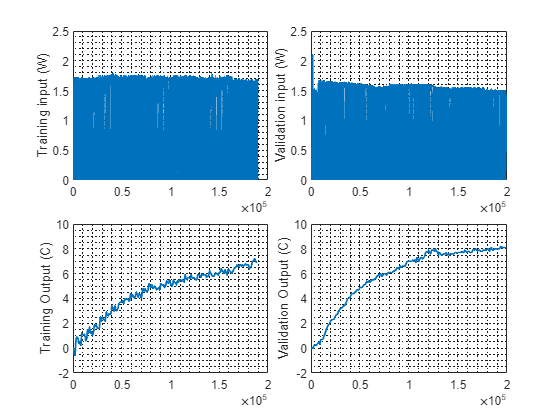

figure
tiledlayout(2,2, "TileSpacing","tight","TileIndexing","columnmajor")
h1 = nexttile;
plot(idd_training.InputData, "LineWidth", 1.5)
ylabel("Training input (W)")
h2 = nexttile;
plot(idd_training.OutputData)
ylabel("Training Output (C)")
linkaxes([h1 h2], 'x')
h3 = nexttile;
plot(idd_validations{1}.InputData, "LineWidth", 1.5)
ylabel("Validation input (W)")
h4 = nexttile;
plot(idd_validations{1}.OutputData)
ylabel("Validation Output (C)")
linkaxes([h3 h4], 'x')
ylimsO = [min(h2.YLim(1), h4.YLim(1)),max(h2.YLim(2), h4.YLim(2)) * 1.0];
h2.YLim = ylimsO;
h4.YLim = ylimsO;
ylimsI = [min(h1.YLim(1), h3.YLim(1)), max(h1.YLim(2), h3.YLim(2)) * 1.0];
h1.YLim = ylimsI;
h3.YLim = ylimsI;

## Run model fitting

We target a continuous LTI model with 1 pole:


$$\frac{\Delta T}{P} = \frac{R_T}{ \tau \cdot s+ 1}$$


where the fitted parameters are

$R_T$ = thermal resistance

$\tau$ = thermal time constant

opt = procestOptions;
opt.InitialCondition =  "zero";
model = procest(idd_training, "P1", opt);

## Plot results

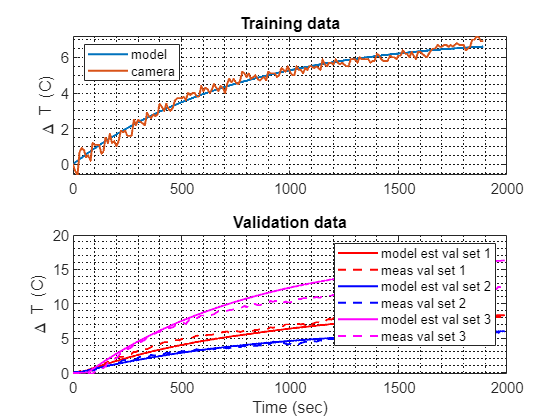

[rmse, fig_handle] = plot_results(model, idd_training, idd_validations, n_validation_sets, training_Ts, validation_Ts);


% exportgraphics(fig_handle, "results.png")
% print -clipboard -dbitmap

## Model discretization

The resulting model is here discretized with Tustin. The parameters used also involve the phase resistance $R_T$, which is used to compute the dissipated power in the architectural model:


$$P=R_T \cdot \;\left(I_{q,\;\textrm{RMS}}^2 +I_{d,\;\textrm{RMS}}^2 \right)$$


% Symbolic variables
syms R_L R_T T_s tau z
s = sym('s');

% Numerical values
RlV = single(25.9);  
RtV = single(model.Kp)

RtV = single
        16.00648

tauV = single(model.Tp1)

tauV = single
        797.4931

TsV = 1e-2;

continuous_model_sym = R_L * R_T / (tau * s + 1)

$$continuous\_model\_sym = \frac{R_{L}\,R_{T}}{s\,\tau +1}$$


tustin_conversion = 2/T_s * (z - 1)/(z+1);

discrete_model_sym = simplifyFraction(subs(continuous_model_sym, s, tustin_conversion))

$$discrete\_model\_sym = \frac{R_{L}\,R_{T}\,T_{s}\,\left(z+1\right)}{T_{s}-2\,\tau +T_{s}\,z+2\,\tau \,z}$$


discrete_model = simplify(subs(discrete_model_sym, [R_L R_T T_s tau], [RlV RtV TsV tauV]));